# Plot each Spectrogram to look for artifacts

## Set Parameters for Chronux Spectrogram

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


##  Load and Plot Each Dataset

I have removed CT7 and KO7 here as the trials were noisy

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT4, CT5, CT6, CT8}

controls = 1×3 cell array
    {1893260×2 single}    {3716176×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO4, KO5, KO6, KO8}

knockouts = 1×3 cell array
    {1890190×2 single}    {3517539×2 single}    {3861380×2 single}


## Vertically Concatenate Datasets

CTL_cat = vertcat_cell_array(controls);

x = 1893260×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 5609436×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


result = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


KO_cat = vertcat_cell_array(knockouts);

x = 1890190×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 5407729×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


result = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


# Filter Noise

## Filter out 60 Hz Signal from Each

% removing 60 Hz
alpha = 0.9965

alpha = 0.9965

CTL_no60 = filter_noise(CTL_cat, 60, params.Fs, alpha)

xarray = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0588
    0.0165   -0.0736
    0.0149   -0.0634
    0.0156   -0.0762
    0.0123    0.0017
    0.0146   -0.0046
    0.0152   -0.0102
    0.0136   -0.0233
    0.0156   -0.0405


result = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0588
    0.0165   -0.0736
    0.0149   -0.0634
    0.0156   -0.0762
    0.0123    0.0017
    0.0146   -0.0046
    0.0152   -0.0102
    0.0136   -0.0233
    0.0156   -0.0405


CTL_no60 = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0588
    0.0165   -0.0736
    0.0149   -0.0634
    0.0156   -0.0762
    0.0123    0.0017
    0.0146   -0.0046
    0.0152   -0.0102
    0.0136   -0.0233
    0.0156   -0.0405


KO_no60 = filter_noise(KO_cat, 60, params.Fs, alpha)

xarray = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0756
    0.0024   -0.0449
    0.0054   -0.0553
    0.0034   -0.0405
    0.0037    0.0109
    0.0044   -0.0802
    0.0050   -0.0507
    0.0031   -0.0681
    0.0027   -0.0698


result = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0756
    0.0024   -0.0449
    0.0054   -0.0553
    0.0034   -0.0405
    0.0037    0.0109
    0.0044   -0.0802
    0.0050   -0.0507
    0.0031   -0.0681
    0.0027   -0.0698


KO_no60 = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0756
    0.0024   -0.0449
    0.0054   -0.0553
    0.0034   -0.0405
    0.0037    0.0109
    0.0044   -0.0802
    0.0050   -0.0507
    0.0031   -0.0681
    0.0027   -0.0698


# Remove Artifacts

In this section I remove artifacts from the data by filtering all signal beyond a modular limit (here limit = 0.5 mV) 

## Set Limit in mV

% Set limit 
limit = 0.5

limit = 0.5000

## Remove Artifacts 

% Filter 
CTL_cat_filter = artifact_filter(CTL_no60, limit)

result = 9222688×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0588
    0.0165   -0.0736
    0.0149   -0.0634
    0.0156   -0.0762
    0.0123    0.0017
    0.0146   -0.0046
    0.0152   -0.0102
    0.0136   -0.0233
    0.0156   -0.0405


CTL_cat_filter = 9222688×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0588
    0.0165   -0.0736
    0.0149   -0.0634
    0.0156   -0.0762
    0.0123    0.0017
    0.0146   -0.0046
    0.0152   -0.0102
    0.0136   -0.0233
    0.0156   -0.0405


KO_cat_filter = artifact_filter (KO_no60, limit)

result = 9240560×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0756
    0.0024   -0.0449
    0.0054   -0.0553
    0.0034   -0.0405
    0.0037    0.0109
    0.0044   -0.0802
    0.0050   -0.0507
    0.0031   -0.0681
    0.0027   -0.0698


KO_cat_filter = 9240560×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0756
    0.0024   -0.0449
    0.0054   -0.0553
    0.0034   -0.0405
    0.0037    0.0109
    0.0044   -0.0802
    0.0050   -0.0507
    0.0031   -0.0681
    0.0027   -0.0698


## Plot Raw Trace Before & After Artifact Filter

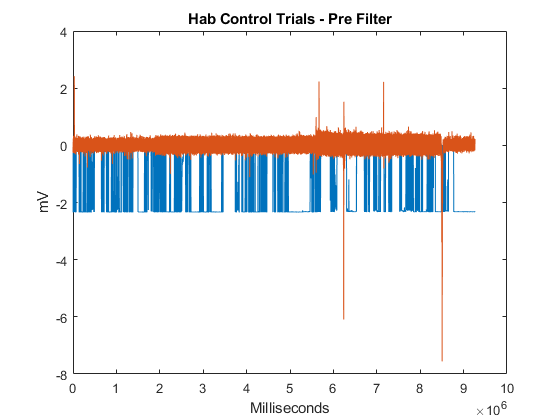

% Plot Artifact Unfiltered

figure; plot (CTL_cat); title('Hab Control Trials - Pre Filter'); xlabel('Milliseconds'); ylabel('mV');

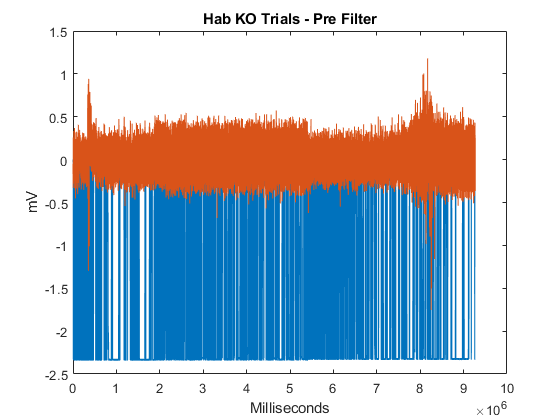

figure; plot (KO_cat); title('Hab KO Trials - Pre Filter'); xlabel('Milliseconds'); ylabel('mV');

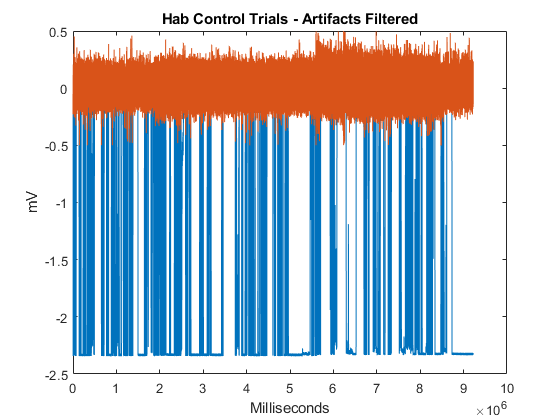


% Plot Artifact Filtered
figure; plot(CTL_cat_filter); title('Hab Control Trials - Artifacts Filtered'); xlabel('Milliseconds'); ylabel('mV');

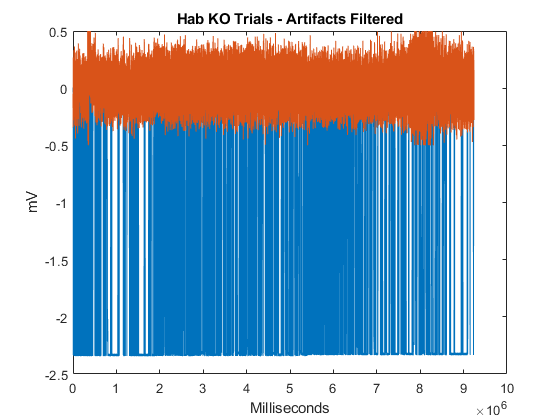

figure; plot(KO_cat_filter); title('Hab KO Trials - Artifacts Filtered'); xlabel('Milliseconds'); ylabel('mV');

## Plot Spectrogram Before & After Artifact Filter

%Set movingwin ([Seconds Step_Size])
movingwin = [20 1]

movingwin =     20     1


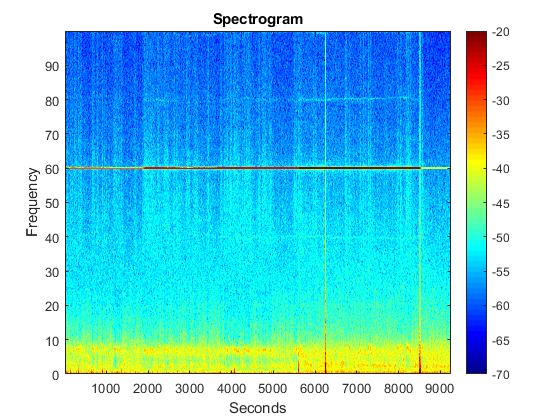


% Plot Artifact Unfiltered
plot_spectrogram(CTL_cat, movingwin, params)

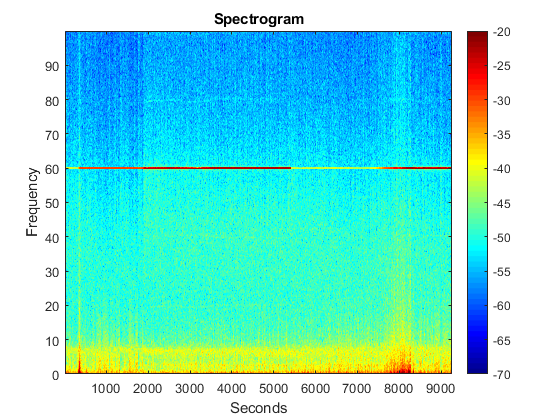

plot_spectrogram(KO_cat, movingwin, params)

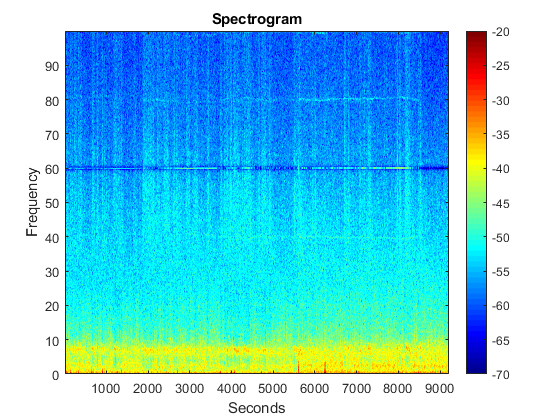


% Plot Artifact Filtered
plot_spectrogram(CTL_cat_filter, movingwin, params)

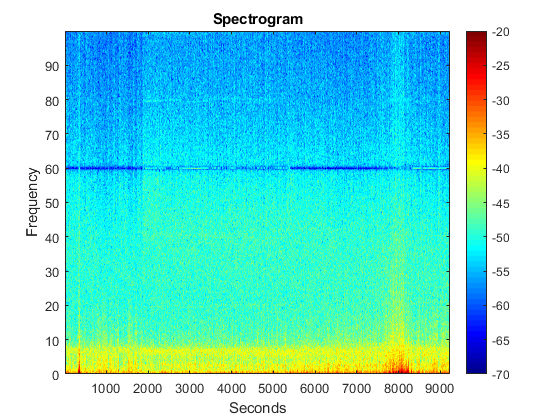

plot_spectrogram(KO_cat_filter, movingwin, params)

## Plot Spectrum_Seg20 Before & After Artifact Filter 

% Set Window to average over (seconds)
win = 20

win = 20

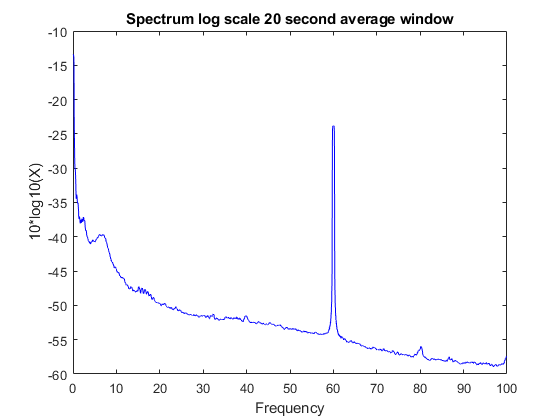

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}



% Plot Artifact Unfiltered 
%plot_spectrum_seg(CTL_cat, win, params)

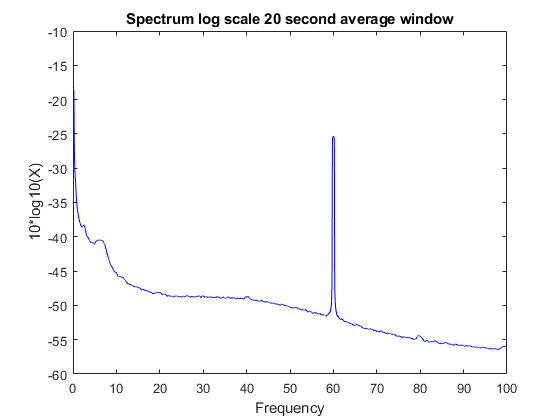

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


%plot_spectrum_seg(KO_cat, win, params)

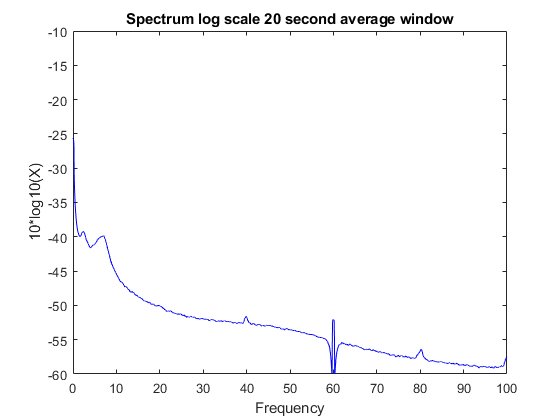

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}



% Plot Artifact Filtered
plot_spectrum_seg(CTL_cat_filter, win, params)

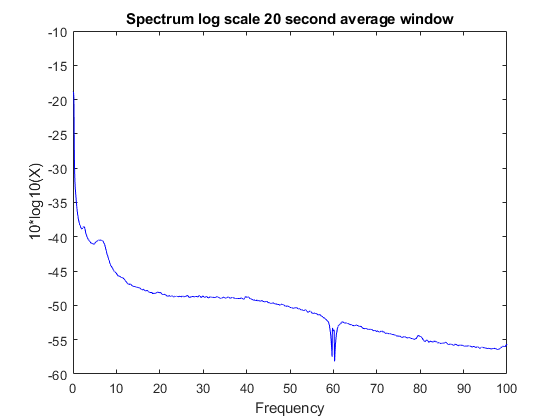

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


plot_spectrum_seg(KO_cat_filter, win, params)



%ending here 10PM 4/30

## Plot Spectrum Segs Together

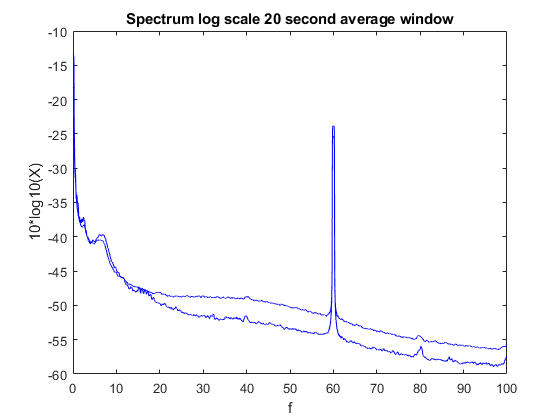

result = 1×2 cell array
    {1×3 cell}    {1×3 cell}


ans = 1×2 cell array
    {1×3 cell}    {1×3 cell}


%plot_spectrum_seg_t(CTL_cat, KO_cat, win, params)

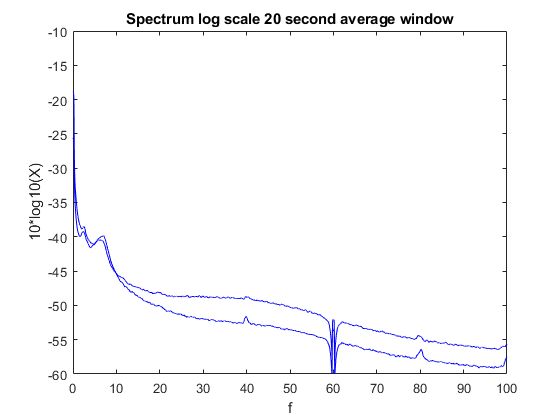

result = 1×2 cell array
    {1×3 cell}    {1×3 cell}


ans = 1×2 cell array
    {1×3 cell}    {1×3 cell}



plot_spectrum_seg_t(CTL_cat_filter, KO_cat_filter, win, params)

## Plot Spectrum_Seg20 After Noise Filter 

% Set Window to average over (seconds)
win = 20

win = 20

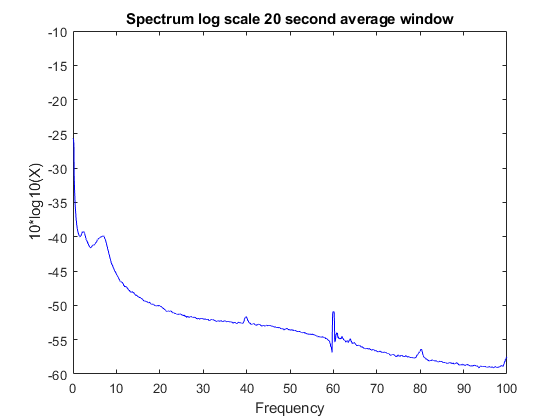

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


zz = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}




% Plot Artifact Filtered
zz = plot_spectrum_seg(CTL_fn, win, params)

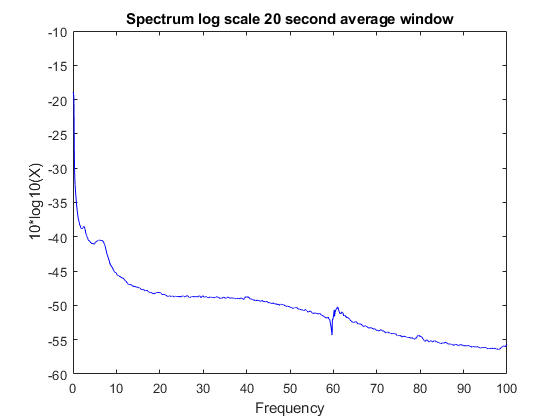

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


xx = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


xx = plot_spectrum_seg(KO_fn, win, params)

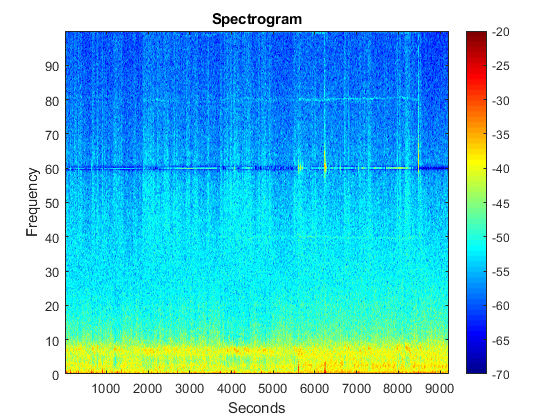

plot_spectrogram(CTL_fn, movingwin, params)

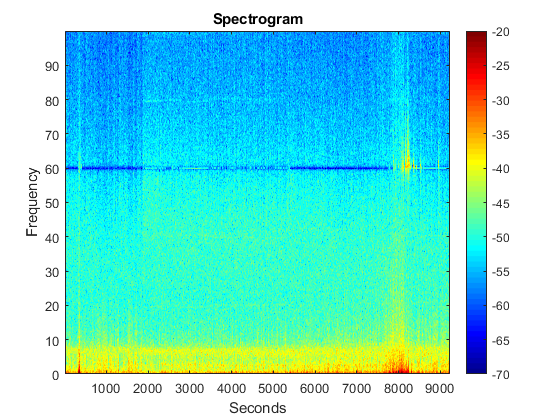

plot_spectrogram(KO_fn, movingwin, params)

# Functions

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}) 
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f, Serr]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
result = {S,f, Serr}
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency');

end

## Calculate and Plot Spectrum Segs Together

function result = plot_spectrum_seg_t (arrayx, arrayz, window, params)

% window is length in seconds to average over
segave = 1 ;

% Calculate 
[S1,f1, Serr1]=mtspectrumsegc(arrayx(:,2),window,params,segave);

[S2,f2, Serr2]=mtspectrumsegc(arrayz(:,2),window,params,segave);


% Plot
figure; plot_vector(S1,f1, 'l', Serr1); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
hold on 
plot_vector(S2,f2, 'l', Serr2)

result = {{S1,f1, Serr1}, {S2 f2 Serr2}}
end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array
end

## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:)
end
result = cell_array
end


## Remove and Frequency Noise from Cell Array of Datasets

function result = filter_noise(xarray, noiseHz, Fs, alpha)
% This function removes noise from signal with variable alpha and Hz

% Set parameters for filter

omega = 2*pi*noiseHz/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end